clearvars
%define the grid
Nx = 600;%600
Ny = 450;%450
dx = 2e-4;%2e-4
dy = 2e-4;%2e-4
Kgrid = kWaveGrid(Nx,dx,Ny,dy);
c = 1500;
%Kgrid.setTime

%Use point per wavelength ppl to reduce dx until stable
%dx = 2e-4 ppl = 37500
ppw = 40000;
wavelength = 1.5/120*Nx;
dx_new = wavelength/ppw

dx_new = 1.8750e-04

w = 1500/1e6%1.5mm

w = 0.0015

p = wavelength/dx

p = 37500


%define the medium prperty
medium.sound_speed = 1500;
medium.alpha_coeff = 0.75;
medium.alpha_power = 1.5;

% create the time array
Kgrid.makeTime(medium.sound_speed,0.3,5e-5);%128SQRT2/1500
t_array_new = Kgrid.t_array(1:126)

t_array_new = 1.0e-05 *

         0    0.0040    0.0080    0.0120    0.0160    0.0200    0.0240    0.0280    0.0320    0.0360    0.0400    0.0440    0.0480    0.0520    0.0560    0.0600    0.0640    0.0680    0.0720    0.0760    0.0800    0.0840    0.0880    0.0920    0.0960    0.1000    0.1040    0.1080    0.1120    0.1160    0.1200    0.1240    0.1280    0.1320    0.1360    0.1400    0.1440    0.1480    0.1520    0.1560    0.1600    0.1640    0.1680    0.1720    0.1760    0.1800    0.1840    0.1880    0.1920    0.1960



% define a single source point
source.p_mask = zeros(Nx, Ny);
source.p_mask(70/120*Nx, Ny/2) = 1;

% define a time varying sinusoidal source
source_freq = 1e6;   % [Hz]
source_mag = 3;         % [Pa]
source.p = source_mag * sin(2 * pi * source_freq * t_array_new);
%% 

% filter the source to remove high frequencies not supported by the grid
source.p = filterTimeSeries(Kgrid, medium, source.p);

Filtering input signal...
  maximum frequency supported by kgrid: 3.75MHz (2 PPW)
  filter cutoff frequency: 2.5MHz (3 PPW)
  computation complete.



%define the sensor in a line
x_offset = 20/120*Nx % [grid points]

x_offset = 100

width = 50/90*Ny% [grid points]

width = 250

sensor.mask = zeros(Nx, Ny);
sensor.mask(x_offset, Ny/2 - width/2 + 1:7.8125:Ny/2 + width/2) = 1;

Running k-Wave simulation...
  start time: 30-Jun-2023 11:17:06
  reference sound speed: 1500m/s
  dt: 40ns, t_end: 50us, time steps: 1251
  input grid size: 600 by 450 grid points (120 by 90mm)
  maximum supported frequency: 3.75MHz
  precomputation completed in 0.1866s
  starting time loop...
  estimated simulation time 49.0142s...


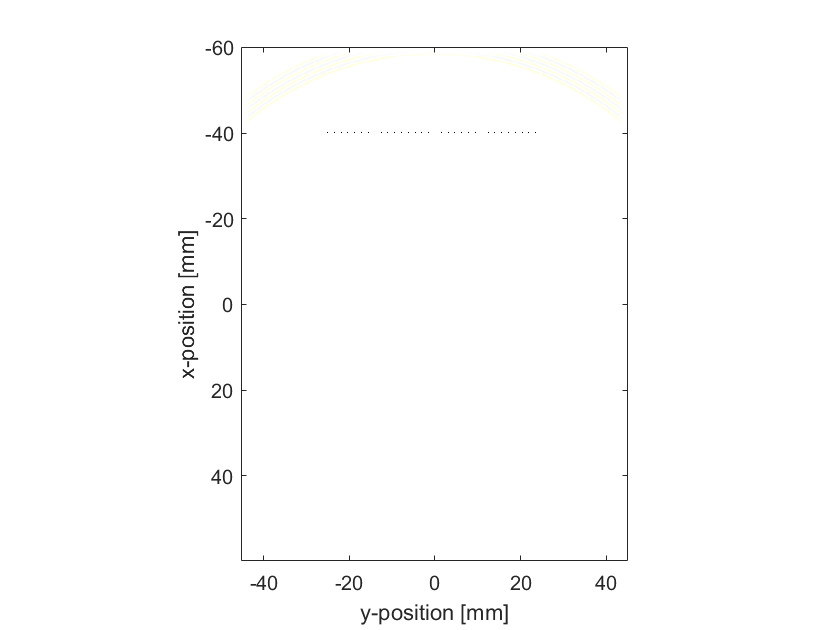

  simulation completed in 50.48s
  total computation time 50.707s


% run the simulation
sensor_data = kspaceFirstOrder2D(Kgrid, medium, source, sensor);

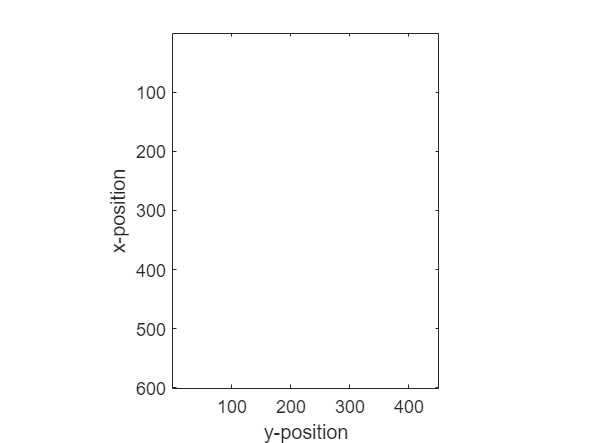


% VISUALISATION
% =========================================================================

% plot the initial pressure and sensor distribution
%positive max around 0.043-0.0449
figure;
%imagesc(Kgrid.y_vec * 1e3, Kgrid.x_vec * 1e3, source.p0 + cart2grid(Kgrid, sensor.mask), [-1, 1]);
imagesc(source.p_mask + sensor.mask, [-1, 1]);
%imagesc(source.p0 + sensor.mask, [-1, 1]);
colormap(getColorMap);
ylabel('x-position');
xlabel('y-position');
axis image;

%% 

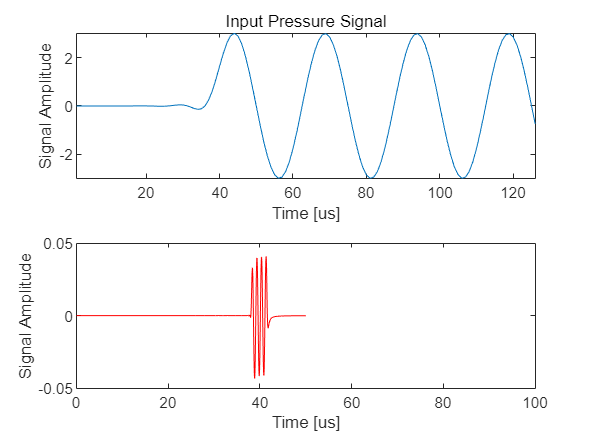


% plot the simulated sensor data
figure;
[t_sc, scale, prefix] = scaleSI(max(t_array_new));

subplot(2, 1, 1);
plot(source.p)
%plot(t_array_new * scale, source.p, 'k-');
xlabel(['Time [' prefix 's]']);
ylabel('Signal Amplitude');
axis ([-inf,inf,-inf,inf]);
title('Input Pressure Signal');

subplot(2, 1, 2);
plot(Kgrid.t_array * scale, sensor_data(32,:), 'r-');
xlabel(['Time [' prefix 's]']);
ylabel('Signal Amplitude');
axis ([0,100,-0.05,0.05]);

%axis tight;
%axis([0,10.5,-inf,inf]);



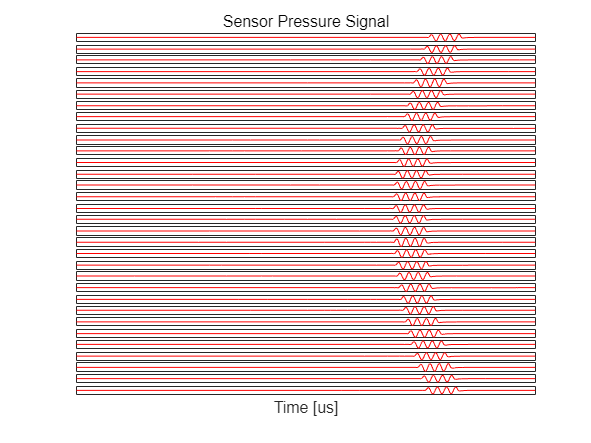

%plot all the 32 original sensor signal 
figure
for i = 1:32
    subplot(32, 1, i);
    plot(Kgrid.t_array * scale, sensor_data(i,:), 'r-');

    %axis([0,10.5,-inf,inf]);
    set(gca,'XTick',[],'YTick',[]);
    if i == 1
            %xlabel(['Time [' prefix 's]']);
            ylabel('Signal Amplitude');
            title('Sensor Pressure Signal');
    end
    if i == 32 
        xlabel(['Time [' prefix 's]']);
        %ylabel('Signal Amplitude');
        %title('Sensor Pressure Signal');
    end

end

%% dt=40ns tend=100.04us timestep = 2502 totalt=1e-4
Kgrid.t_array

ans = 1.0e-04 *

         0    0.0004    0.0008    0.0012    0.0016    0.0020    0.0024    0.0028    0.0032    0.0036    0.0040    0.0044    0.0048    0.0052    0.0056    0.0060    0.0064    0.0068    0.0072    0.0076    0.0080    0.0084    0.0088    0.0092    0.0096    0.0100    0.0104    0.0108    0.0112    0.0116    0.0120    0.0124    0.0128    0.0132    0.0136    0.0140    0.0144    0.0148    0.0152    0.0156    0.0160    0.0164    0.0168    0.0172    0.0176    0.0180    0.0184    0.0188    0.0192    0.0196


t_array_limit = 1/source_freq*5

t_array_limit = 5.0000e-06

t_array_new = Kgrid.t_array(1:32)

t_array_new = 1.0e-05 *

         0    0.0040    0.0080    0.0120    0.0160    0.0200    0.0240    0.0280    0.0320    0.0360    0.0400    0.0440    0.0480    0.0520    0.0560    0.0600    0.0640    0.0680    0.0720    0.0760    0.0800    0.0840    0.0880    0.0920    0.0960    0.1000    0.1040    0.1080    0.1120    0.1160    0.1200    0.1240


1/2E-4

ans = 5000

128*1.414/1500

ans = 0.1207

%obtian all the sensor position
sensorpoistion = zeros(1,32)

sensorpoistion =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j=1

j = 1

for i = 1:450
    if sensor.mask(100,i)==1
        
        sensorpoistion(j) = i;
        j = j+1;
    end
end
sensorpoistion()

ans =    101   109   117   124   132   140   148   156   164   171   179   187   195   203   210   218   226   234   242   249   257   265   273   281   289   296   304   312   320   328   335   343


%distance from sensor to source mm
distance_map = zeros(1,32);
intensitymap = zeros(1,1600);
%sourceposition =[70/120*Nx, Ny/2]%x=350,y=225
distance = zeros(1,32);
for i = 1:32
    distance(i) = sqrt((sensorpoistion(i)-225)^2+(350-100)^2);
end


%all the source position

%Create a 20mm times 20mm grid, which is 200 times 200
%x from 
map_length = zeros(1,200);
map_width = zeros(1,200);
%x_offset, Ny/2 - width/2 + 1:7.8125:Ny/2 + width/2

for i = 1:200
    map_length(i)=350-Nx/6+i;
    map_width(i)=225-20/90*Ny+i;
end
map_length

map_length =    251   252   253   254   255   256   257   258   259   260   261   262   263   264   265   266   267   268   269   270   271   272   273   274   275   276   277   278   279   280   281   282   283   284   285   286   287   288   289   290   291   292   293   294   295   296   297   298   299   300


map_width

map_width =    126   127   128   129   130   131   132   133   134   135   136   137   138   139   140   141   142   143   144   145   146   147   148   149   150   151   152   153   154   155   156   157   158   159   160   161   162   163   164   165   166   167   168   169   170   171   172   173   174   175


%x = 350-map_width:350+map_width
%y = 225-map_width:225+map_width


%the intensity map position
%map_width = 40/120*Nx;
%map = zeros(map_width,map_width);

%store the map postion
step = zeros(1,32)

step =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


sensor_data_test = zeros(32,1251);
sensor_data_new = zeros(32,1251);
coeff = 4/32*pi;
%times distance with the sensor data3m
A = zeros(32,1251)

A =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

%define the energy map
energymap = zeros(200,200)

energymap =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0 


sensorpoistion

sensorpoistion =    101   109   117   124   132   140   148   156   164   171   179   187   195   203   210   218   226   234   242   249   257   265   273   281   289   296   304   312   320   328   335   343


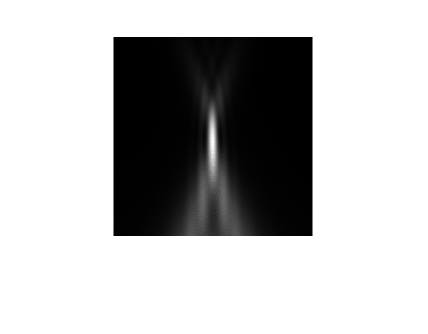

for m = 1:200
     for n = 1:200
         A = zeros(32,1251);
        for i = 1:32
            %calculate distance from each point
            distance_map(1,i)=sqrt((sensorpoistion(i)-map_width(m))^2+(map_length(n)-100)^2);
            timeshift = distance_map*dx/c;

            
            %apply the time delay to the sensor data
            step(i) = floor(timeshift(i)/4e-8);
            sensor_data_test(i,:) = sensor_data(i,:);
            sensor_data_new(i,:) = circshift(sensor_data_test(i,:), -step(i));
            A(i,:) = distance_map(i)*sensor_data_new(i,:);
        end
        %sum 32 sensor data together
        sum_A = sum(A);
        intensity = coeff * sum_A;

        %integral'
        intensity_2 = intensity.^2;
        Q = trapz(intensity_2);
        coeff2 = 1/(4*pi*1500);
%         energymap(n,m)= intensity_2*intensity_2'/32/32*coeff2;
        energymap(n,m)= Q*coeff2;
     end
end

figure
imshow(energymap,[])

intensity_2*intensity_2'/32/32

ans = 1.1190e+03

Q

Q = 8.9213e+03

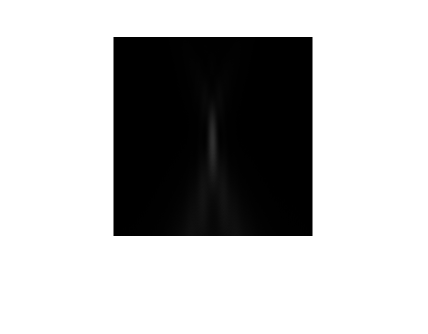

figure

%imshow(energymap/256)

imshow(uint8(energymap))

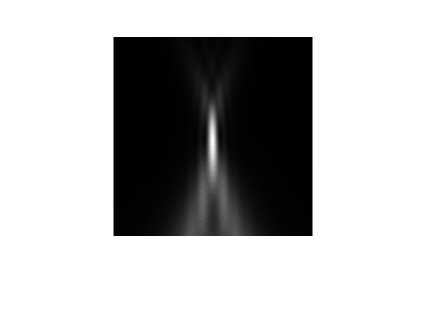

rea = im2uint8(mat2gray(energymap));
figure
imshow(rea)


% step
% timeshift
% distance_map
% for m = 1:200
%     for n = 1:200
%         i
%         for i = 1:32
%             %calculate distance from each point
%             distance_map(1,i)=sqrt((sensorpoistion(i)-map_width(n))^2+(map_length(m)-100)^2);
%             timeshift = distance_map*dx/c;
% 
%             
%             %apply the time delay to the sensor data
% %             step(i) = floor(tj(i)/4e-8);
% %             sensor_data_test(i,:) = sensor_data(i,:);
% %             sensor_data_new(i,:) = circshift(sensor_data_test(i,:), -step(i));

%         end
%     end
% end

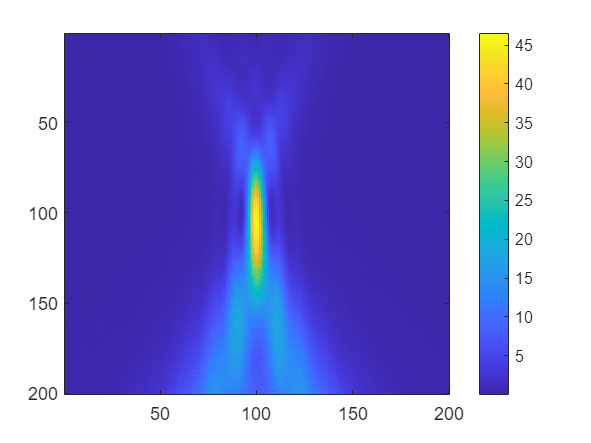


figure

%imshow(energymap/256)

%imshow(uint8(energymap))
imagesc(energymap);
colorbar;  % colorbar 的作用是生成一个代表颜色值的条状图例

%source strength = 4pi/N*sum(distance*signal)

coeff = 4/32*pi

coeff = 0.3927

%distance_total = sum(distance, 'all')


%Shift test
%1st calculate how much time step to move
% step = tj(1)/4e-8%how many step to move
% step = floor(step)
% sensor_data_test = sensor_data(1,:)
% sensor_data_new = circshift(sensor_data_test, -step)

%shift test2
% function [AfterArray] = ArrayDisplacement(BeforeArray,direction,len,type)
% ArrayEnd = length(BeforeArray);
% eforeArrayL = BeforeArray(1:len);
% BeforeArrayR = BeforeArray(len+1:ArrayEnd);
% BeforeArrayL = fliplr(BeforeArrayL);
% BeforeArrayR = fliplr(BeforeArrayR);
% BeforeArray = [BeforeArrayL BeforeArrayR];
% AfterArray = fliplr(BeforeArray);

%apply the time delay to the sensor data
step = zeros(1,32)

step =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


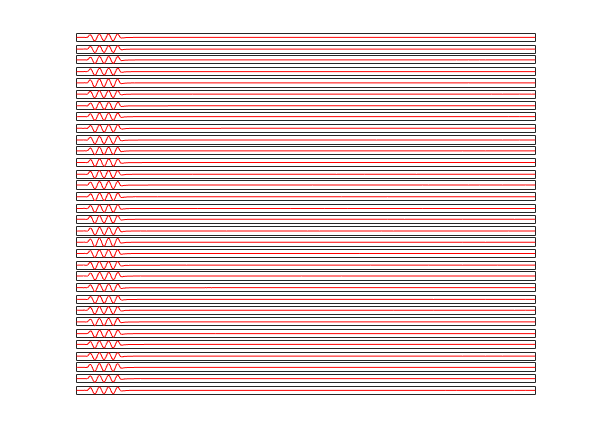

sensor_data_test = zeros(32,1251);
sensor_data_new = zeros(32,1251);
tj = distance*dx/c;
for i = 1:32
    step(i) = floor(tj(i)/4e-8);
    sensor_data_test(i,:) = sensor_data(i,:);
    sensor_data_new(i,:) = circshift(sensor_data_test(i,:), -step(i));
    %plot the shifted data 
    subplot(32, 1, i);
    plot(Kgrid.t_array * scale, sensor_data_new(i,:), 'r-');
    set(gca,'XTick',[],'YTick',[]);
    %axis([0,10.5,-inf,inf]);
end

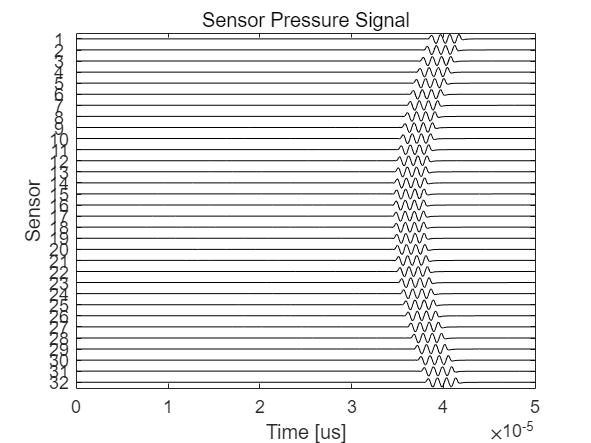

figure

stackedPlot(Kgrid.t_array,sensor_data)
ylabel('Sensor');
xlabel(['Time [' prefix 's]']);
title('Sensor Pressure Signal');

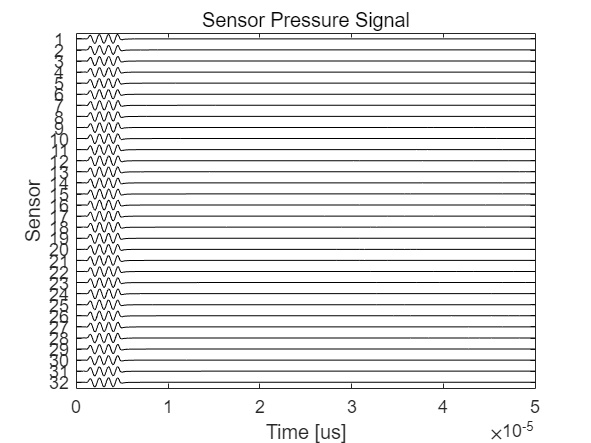


figure
stackedPlot(Kgrid.t_array,sensor_data_new)
ylabel('Sensor');
xlabel(['Time [' prefix 's]']);
title('Sensor Pressure Signal');

%calculate intensity
figure
A = zeros(32,1251)

A =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

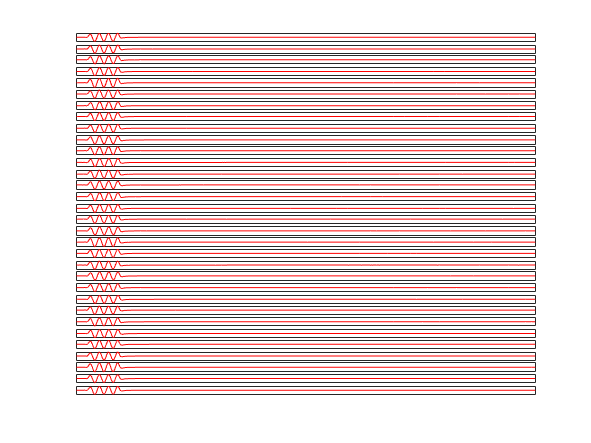

A(1,:) = distance(1)*sensor_data_new(1,:);
for i = 1:32
    A(i,:) = distance(i)*sensor_data_new(i,:);
    subplot(32, 1, i);
    plot(Kgrid.t_array * scale, A(i,:), 'r-');
    set(gca,'XTick',[],'YTick',[]);
end

figure
sum_A = sum(A)

sum_A =    -0.0084    0.0209    0.0246   -0.0018   -0.0388   -0.0599   -0.0527   -0.0262    0.0023    0.0259    0.0536    0.0939    0.1293    0.1056   -0.0452   -0.3518   -0.7476   -1.0524   -1.0188   -0.4456    0.6795    2.0687    3.1262    3.0895    1.3179   -2.3328   -7.1629  -11.4458  -12.5287   -7.2690    7.2413   32.8244   69.4738  114.9588  164.9288  213.5176  254.2933  281.3051  289.9798  277.7084  244.0742  190.7690  121.2801   40.4353  -46.1189 -132.4375 -212.7381 -281.7649 -335.0573 -369.1534



%plot(Kgrid.t_array * scale, sum_A, 'r-');
intensity = coeff * sum_A

intensity =    -0.0033    0.0082    0.0097   -0.0007   -0.0152   -0.0235   -0.0207   -0.0103    0.0009    0.0102    0.0211    0.0369    0.0508    0.0415   -0.0178   -0.1381   -0.2936   -0.4133   -0.4001   -0.1750    0.2669    0.8124    1.2276    1.2132    0.5175   -0.9161   -2.8129   -4.4948   -4.9200   -2.8545    2.8437   12.8901   27.2823   45.1442   64.7674   83.8481   99.8607  110.4682  113.8748  109.0558   95.8477   74.9148   47.6266   15.8789  -18.1108  -52.0081  -83.5421 -110.6488 -131.5767 -144.9662


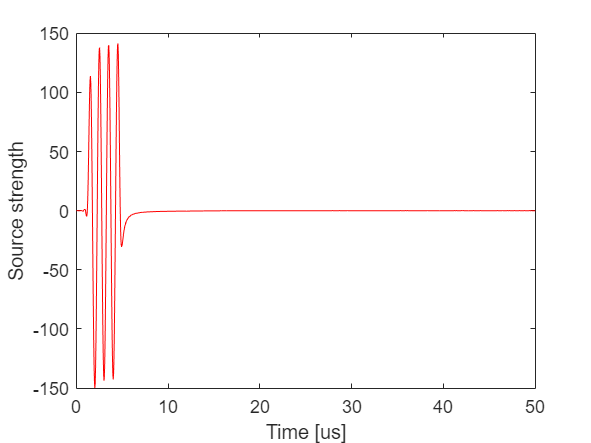

plot(Kgrid.t_array * scale, intensity, 'r-');
xlabel(['Time [' prefix 's]']);
ylabel('Source strength');

%integral'
intensity_2 = intensity.^2;
Q = trapz(intensity_2)

Q = 8.5455e+05

coeff2 = 1/(4*pi*1500)

coeff2 = 5.3052e-05

%fun = @(x) exp(-x.^2).*log(x).^2;
fun = @(x) (coeff2*sum(A)).^2

fun = 包含以下值的 function_handle :
    @(x)(coeff2*sum(A)).^2


%fun_2 = fun.^2
q = integral(fun,0,5e-05,'ArrayValued',true)

q = 1.0e-07 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0002    0.0002    0.0001    0.0001    0.0015    0.0068    0.0186    0.0383    0.0642    0.0910    0.1114    0.1183    0.1085    0.0838    0.0512    0.0207    0.0023    0.0030    0.0247    0.0637    0.1117    0.1580    0.1918


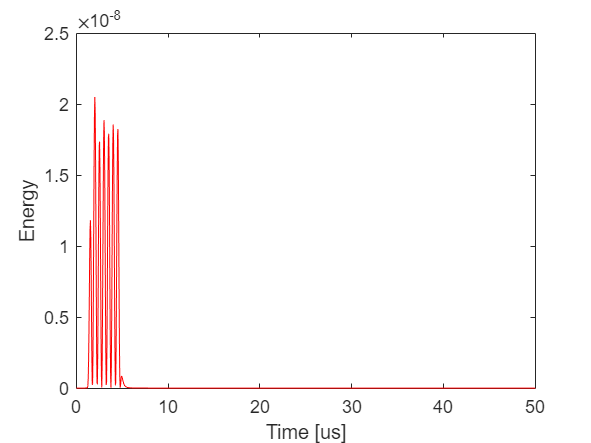

figure
plot(Kgrid.t_array * scale, q, 'r-');
xlabel(['Time [' prefix 's]']);
ylabel('Energy');


%original received signal
step(1)

ans = 930

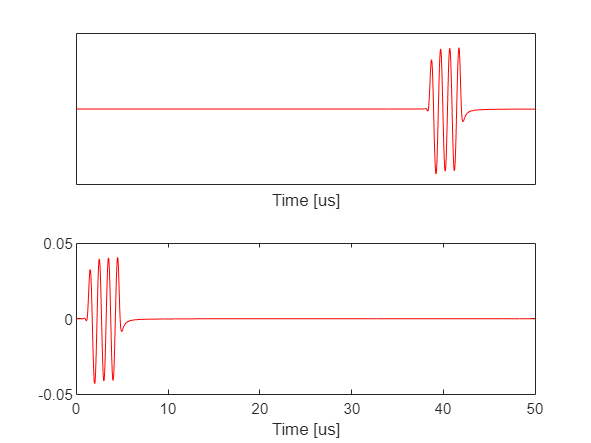

%sensor_data_new(1,:) = circshift(sensor_data_test(1,:), -step);
figure
subplot(2,1,1);
plot(Kgrid.t_array * scale, sensor_data_test(1,:), 'r-');
set(gca,'XTick',[],'YTick',[]);
xlabel(['Time [' prefix 's]']);
%shifted signal
subplot(2,1,2);
plot(Kgrid.t_array * scale, sensor_data_new(1,:), 'r-');
xlabel(['Time [' prefix 's]']);


% sensor_data_new = distance * sensor_data
% figure
% subplot(2,1,1);
% plot(Kgrid.t_array * scale, sensor_data_new, 'r-');
% subplot(2,1,2);
% plot(Kgrid.t_array * scale, sensor_data(31,:), 'r-');


help kWaveGrid

 kWaveGrid Class definition for k-Wave grid.
 
  DESCRIPTION:
      kWaveGrid is the grid class used across the k-Wave Toolbox. An object
      of the kWaveGrid class contains the grid coordinates and wavenumber
      matrices used within the simulation and reconstruction functions in
      k-Wave. The grid matrices are indexed as: (x, 1) in 1D; (x, y) in
      2D; and (x, y, z) in 3D. The grid is assumed to be a regularly spaced
      Cartesian grid, with grid spacing given by dx, dy, dz (typically the
      grid spacing in each direction is constant). 
 
  USAGE:
      kgrid = kWaveGrid(Nx, dx)
      kgrid = kWaveGrid(Nx, dx, Ny, dy)
      kgrid = kWaveGrid(Nx, dx, Ny, dy, Nz, dz)
 
  INPUTS:
      Nx, Ny, Nz      - number of grid points in each Cartesian direction
      dx, dy, dz      - grid point spacing in each Cartesian direction [m]
 
  OUTPUTS:
      kgrid           - 